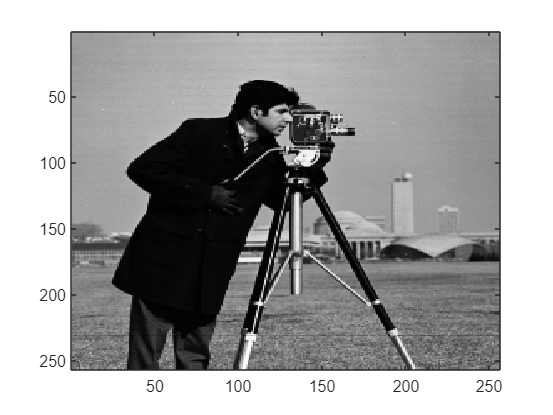

%experimentation with upsampling an image
%IMAGE UPSAMPLING
%Upsampling is the process of inserting zeros in between the signal value in order to increase the size of the matrix.

A = imread('C:\Users\tvasu\Downloads\cameraman.tif');
figure,imagesc(A);colormap("gray");

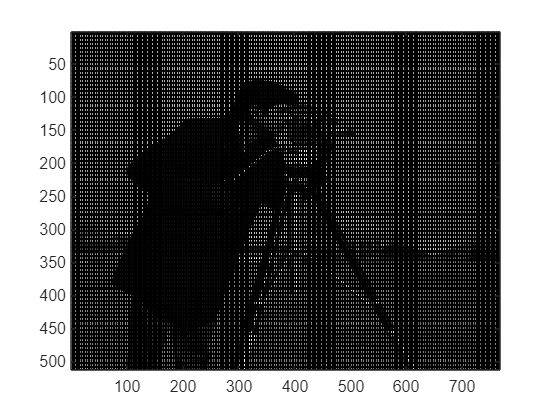


M = 2;
N = 3;

B = zeros([size(A,1)*M size(A,2)*N]);
B(1:M:end,1:N:end) = A;

figure,imagesc(B);colormap(gray);

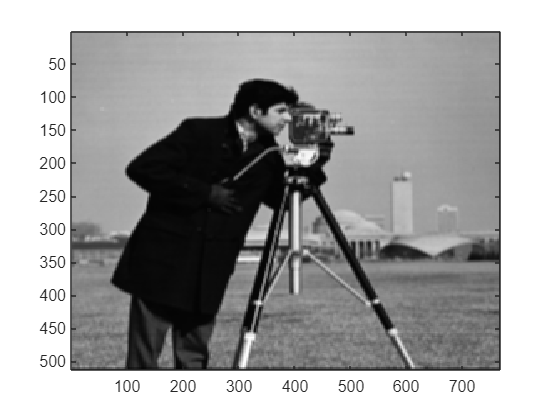

sz = M*N;
H = fspecial('average',[sz sz]);
C = conv2(B,H,'same');

figure,imagesc(C);colormap(gray);